# Super Resolution Workflow

## Add Files

addpath 'Common Functions'
addpath 'Models'
addpath 'SuperResolution'

## Load Files

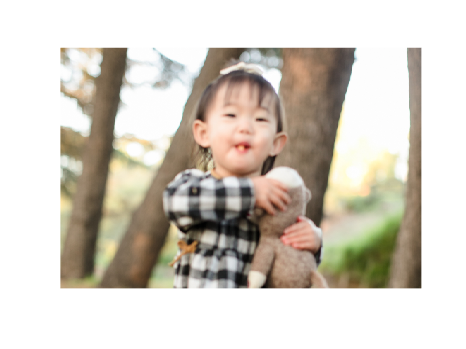

Image_name = 'child.jpeg';
image = imread(Image_name);
imshow(image);

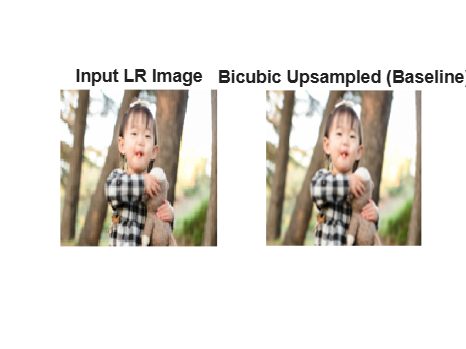

factor = 4;
img_LR  = imresize(image, [128 128]);
img_HR_size = size(img_LR, 1) * factor;
% Bicubic baseline for visual comparison
img_LR_up = imresize(img_LR, [img_HR_size img_HR_size], 'bicubic');

% Display
figure;
subplot(1,2,1); imshow(img_LR);    title('Input LR Image');
subplot(1,2,2); imshow(img_LR_up); title('Bicubic Upsampled (Baseline)');

## Define CNN and Noise Tensor

% Initial Network Parameters
input_depth  = 3;
num_channels = 64;
num_classes  = 3;
kernel_size  = 3;
imgSize = [img_HR_size, img_HR_size, input_depth];
%--- Define CNN ---
net = InpaintUnet3(imgSize, num_classes);
% Count parameters
totalParams = 0;
lrnables = net.Learnables;
for i = 1:height(lrnables)
    totalParams = totalParams + numel(extractdata(lrnables.Value{i}));
end
fprintf('Number of params: %d\n', totalParams);

Number of params: 1023203


% --- Noise Tensor ---
net_input       = get_noise(input_depth, 'noise', img_HR_size);
net_input_saved = dlarray(single(net_input), 'SSCB');

% Prepare LR image
img_LR_nom = im2double(img_LR);
img_LR_dl  = dlarray(single(img_LR_nom), 'SSCB');

## Loss and Gradient Function

function loss = computeSRLoss(out_HR, img_LR_dl, factor, lambda_tv)
    % Downsample HR output to LR size via average pooling
    out_LR = avgpool(out_HR, [factor factor], 'Stride', [factor factor], 'Padding', 'same');
    mse_loss = mean((out_LR - img_LR_dl).^2, 'all');

    %Total Variation: penalise spatial gradients in output  
    dx = out_HR(:, 2:end, :, :) - out_HR(:, 1:end-1, :, :);
    dy = out_HR(2:end, :, :, :) - out_HR(1:end-1, :, :, :);
    tv_loss = mean(abs(dx), 'all') + mean(abs(dy), 'all');

    loss = mse_loss + lambda_tv * tv_loss;
end

function [loss, gradients, out_HR, out_avg] = modelGradientsSR( ...
        net, net_input_saved, img_LR_dl, out_avg, exp_weight, reg_noise_std, factor)

   
    if reg_noise_std > 0
        noise = dlarray(randn(size(extractdata(net_input_saved)), 'single'), 'SSCB');
        net_input = net_input_saved + noise * reg_noise_std;
    else
        net_input = net_input_saved;
    end

    % Forward pass -> HR output
    out_HR = forward(net, net_input);

    % Loss: consistency with LR observation + TV smoothness on HR
    loss = computeSRLoss(out_HR, img_LR_dl, factor, 1e-4);

    % Exponential moving average of outputs (smoothed result)
    out_detached = dlarray(extractdata(out_HR), 'SSCB');
    if isempty(out_avg)
        out_avg = out_detached;
    else
        out_avg = out_avg * exp_weight + out_detached * (1 - exp_weight);
    end

    gradients = dlgradient(loss, net.Learnables);
end

## Optimization Steps

Iter 00001  Loss 0.112812  PSNR_LR: 9.4561
Iter 00002  Loss 0.094489  PSNR_LR: 10.2391
Iter 00003  Loss 0.086447  PSNR_LR: 10.6279
Iter 00004  Loss 0.077637  PSNR_LR: 11.0959
Iter 00005  Loss 0.076577  PSNR_LR: 11.1556
Iter 00006  Loss 0.071847  PSNR_LR: 11.4333
Iter 00007  Loss 0.068854  PSNR_LR: 11.6184
Iter 00008  Loss 0.063133  PSNR_LR: 11.9955
Iter 00009  Loss 0.064816  PSNR_LR: 11.8813
Iter 00010  Loss 0.065623  PSNR_LR: 11.8270
Iter 00011  Loss 0.063922  PSNR_LR: 11.9415
Iter 00012  Loss 0.060862  PSNR_LR: 12.1543
Iter 00013  Loss 0.061830  PSNR_LR: 12.0861
Iter 00014  Loss 0.060523  PSNR_LR: 12.1792
Iter 00015  Loss 0.060180  PSNR_LR: 12.2040
Iter 00016  Loss 0.060820  PSNR_LR: 12.1584
Iter 00017  Loss 0.062481  PSNR_LR: 12.0411
Iter 00018  Loss 0.058816  PSNR_LR: 12.3041
Iter 00019  Loss 0.063241  PSNR_LR: 11.9885
Iter 00020  Loss 0.058018  PSNR_LR: 12.3635
Iter 00021  Loss 0.061813  PSNR_LR: 12.0884
Iter 00022  Loss 0.057519  PSNR_LR: 12.4013
Iter 00023  Loss 0.058330  PSNR_L

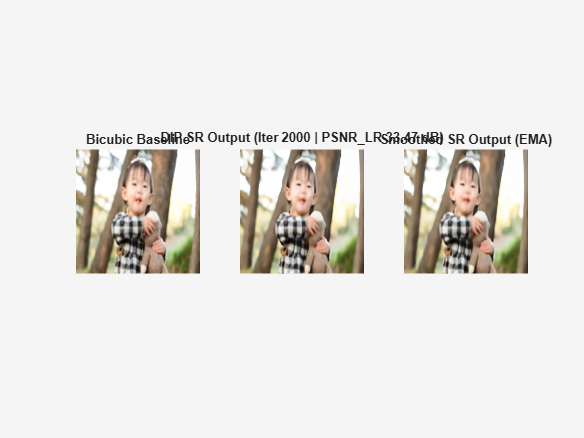

if factor == 4
    num_iter      = 2000;
    reg_noise_std = 0.03;
elseif factor == 8
    num_iter      = 4000;
    reg_noise_std = 0.05;
else
    error('Only upscaling factors 4 or 8 are supported.');
end

LR = 0.01;
exp_weight = 0.99;
show_every = 10;
PLOT  = 1;
out_avg = [];
trailingAvg = [];
trailingAvgSq = [];
psnr_LR_last = -inf;
last_learnables = [];

% --- Training Loop ---
for iter = 1:num_iter

    [loss, gradients, out_HR, out_avg] = dlfeval(@modelGradientsSR, ...
        net, net_input_saved, img_LR_dl, out_avg, exp_weight, reg_noise_std, factor);

    [net, trailingAvg, trailingAvgSq] = adamupdate(net, gradients, ...
        trailingAvg, trailingAvgSq, iter, LR);

    % --- Convert dlarray to numeric ---
    out_HR_num  = double(gather(extractdata(out_HR)));
    out_HR_num  = out_HR_num(:,:,:,1);
    out_avg_num = double(gather(extractdata(out_avg)));
    out_avg_num = out_avg_num(:,:,:,1);

    % Downsample HR output back to LR size for PSNR vs LR input
    out_LR_num = imresize(out_HR_num, 1/factor);
    psnr_LR    = psnr(out_LR_num, img_LR_nom);

    fprintf('Iter %05d  Loss %.6f  PSNR_LR: %.4f\r', ...
        iter, gather(extractdata(loss)), psnr_LR);

    % --- Start Plotting ---
    if PLOT && mod(iter, show_every) == 0
        out_plt     = min(max(out_HR_num,  0), 1);
        out_avg_plt = min(max(out_avg_num, 0), 1);

        fig = figure(1); clf;
        set(fig, 'Visible', 'on');

        subplot(1,3,1);
        imshow(im2double(img_LR_up)); axis image off;
        title('Bicubic Baseline');

        subplot(1,3,2);
        imshow(out_plt); axis image off;
        title(sprintf('DIP SR Output (Iter %d | PSNR\\_LR %.2f dB)', iter, psnr_LR));

        subplot(1,3,3);
        imshow(out_avg_plt); axis image off;
        title('Smoothed SR Output (EMA)');

        drawnow;
    end

    % --- Back Tracking Logic ---
    if mod(iter, show_every) ~= 0
        if psnr_LR - psnr_LR_last < -5
            fprintf('\nPSNR drop detected — restoring previous checkpoint.\n');
            net.Learnables.Value = last_learnables;
            break;
        else
            last_learnables = net.Learnables.Value;
            psnr_LR_last    = psnr_LR;
        end
    end

end

## Save Weights

% Convert Learnables table to standard numeric values for simple MAT storage
net_weights = net.Learnables;
for k = 1:height(net_weights)
    if isdlarray(net_weights.Value{k})
        net_weights.Value{k} = gather(extractdata(net_weights.Value{k}));
    end
end

% Clip output image to valid [0, 1] range
final_image = min(max(out_avg_num, 0), 1);

mat_filename = 'saved_model_and_image_super_resolution.mat'

mat_filename = 'saved_model_and_image_super_resolution.mat'


% Save network object, extracted weights table, and final output image
save(mat_filename, 'net', 'net_weights', 'final_image');

imwrite(final_image, 'output_image_superres.png');

fprintf('\nSuccessfully saved weights and image to %s\n', mat_filename);


Successfully saved weights and image to saved_model_and_image_super_resolution.mat


## Load and Use Pre Trained Weights and Saved Data

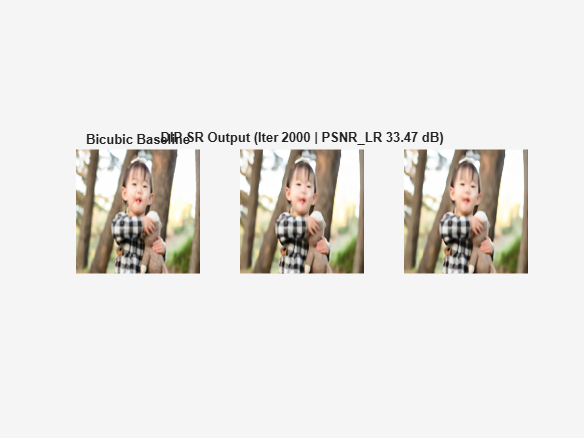

% Load the variables from the MAT-file
data = load('saved_model_and_image_super_resolution.mat');

% Access the saved image
saved_img = data.final_image;
imshow(saved_img);


% Access the restored network
restored_net = data.net;

## See Results Side by Side

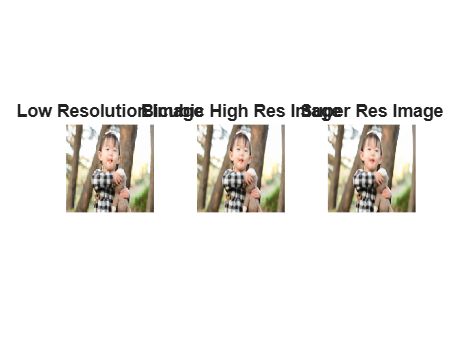

figure;

subplot(1,3,1); imshow(img_LR); title('Low Resolution Image');
subplot(1,3,2); imshow(img_LR_up); title('Bicubic High Res Image');
subplot(1,3,3); imshow(saved_img); title('Super Res Image');